# **UPMC Data Processing Demonstration Script**

## **Basic Example**

#### Load Data and Create Data Store

load FULL_IMPUTED.mat
ds_full = NedocData(TI_full,288);
ds_full = ds_full.setToday(0.99);
ds_full = ds_full.setPPD(48);

data_storef =   Nedoc_Data with properties:

          T_cln: [32181×9 table]
          T_imp: [35328×9 table]
          T_day: [736×8 table]
              X: [1×1 struct]
            X_t: [1×1 struct]
              y: [1×1 struct]
             yp: [1×1 struct]
          today: []
       cls_defs: [16×48 double]
              L: [1×1 struct]
          std__: 0
             mu: []
            sig: []
    splitNotSet: [1×1 MException]


Imputed Table

- filled holes in data set such that each day has desired number of observations

- regression set

#### Transfrom Data

% getmats
[~,yimp] = ds_full.getmats('all','time');
ppd = ds_full.PPD;

x = (1:ppd)';
y = zeros([ds_full.L/ppd,ppd]);
for i = 1:48:length(yimp)-(ppd-1)
    y((i+47)/48,:) = yimp(i:i+(ppd-1));
end

% fits
transform = [x.^0,...
    sin(x*2*pi/ppd), cos(x*2*pi/ppd),...
    sin(x*2*pi/(ppd/2)), cos(x*2*pi/(ppd/2)),...
    sin(x*2*pi/(ppd/4)), cos(x*2*pi/(ppd/4)),...
    sin(x*2*pi/(ppd/8)), cos(x*2*pi/(ppd/8))     ];
y_trans = zeros([size(y,1),size(transform,2)]);

for i = 1:size(y,1)
    y_trans(i,:) = normalEqn(transform,y(i,:)');
end

% view transform
transformed_y = y_trans * transform';
y_prediction = reshape(transformed_y', [], 1);
ds_full = ds_full.setResp(y_prediction);

10/24/2021


[~,avgacc] = ds_full.plot('View Transform', 'tmr', 9)  %#ok<ASGLU,NOPTS>

Transfroms day curves to sums of trig functions

#### Train Model

M = height(ds_full.T_imp) / ppd;
lags = 1:2;
[crnet, mu, sig, Xcell] = trainCRNet_DC(ds_full, lags, y_trans, 100);

#### Load & Plot Predictions

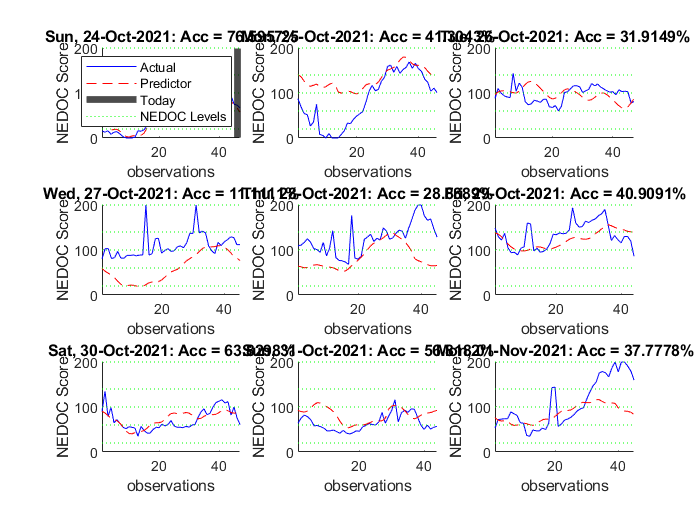

Average Accuracy = 43.24%




coeff_pred_std = predict( crnet, Xcell, "ExecutionEnvironment",'gpu', "MiniBatchSize", max(lags)*9 );
coeff_pred_std = cast(coeff_pred_std,"double");
coeff_pred_std = [zeros([M-size(coeff_pred_std,1) , size(coeff_pred_std,2)]) ; coeff_pred_std];
coeff_pred = sig .* coeff_pred_std + mu;

daypred = coeff_pred * transform';
y_prediction = reshape(daypred', [], 1);

ds_full = ds_full.setResp(y_prediction);

[~,avgacc] = ds_full.plot('ARCRIN Predictions', 'tmr', 9)